R = 3; L = 1; C = 0.5;
A = [0 -1/C; 1/L -R/L];
B = [1/C;  0];
C = [0 R];
D = [0];
x0 = [1 1];	% initial conditions.
t = [0:0.01:5];	% time range is 0 to 5 sec with an increment of 0.01 sec.
u = 0*t ;		% zero input.
[y, x] = lsim(A, B, C, D, u, t, x0)

y =     3.0000
    2.9406
    2.8824
    2.8253
    2.7693
    2.7145
    2.6608
    2.6081
    2.5564
    2.5058


x =     1.0000    1.0000
    0.9802    0.9802
    0.9608    0.9608
    0.9418    0.9418
    0.9231    0.9231
    0.9048    0.9048
    0.8869    0.8869
    0.8694    0.8694
    0.8521    0.8521
    0.8353    0.8353


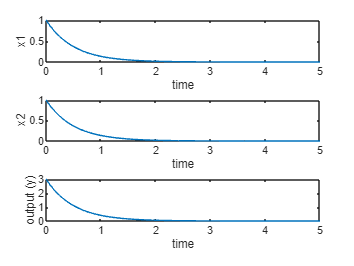

subplot(3, 1, 1);		% divide the figure window into 3 rows and 1 column.
plot(t, x(:,1));		% plot the 1st state variable, column 1 of matrix x.
xlabel('time'); ylabel('x1');
subplot(3, 1, 2);
plot(t, x(:,2));		% plot the 2nd state variable, column 1 of matrix x.
xlabel('time'); ylabel('x2');
subplot(3, 1, 3);
plot(t, y);		           % plot the output y
xlabel('time'); ylabel('output (y)');